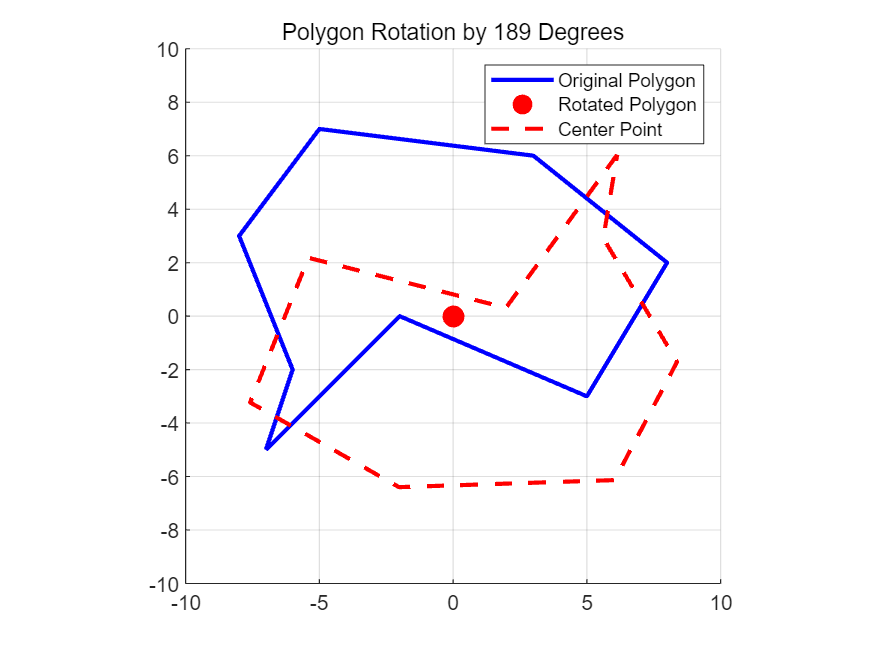

vertices =  [-7 -5; -2 0; 5 -3; 8 2; 3 6; -5 7; -8 3; -6 -2];
id_number = 12210309;  
rotate_polygon(vertices, id_number);

function rotate_polygon(vertices, id_number)
    x_limits = [-10, 10];
    y_limits = [-10, 10];

    x_center = (x_limits(1) + x_limits(2)) / 2;  
    y_center = (y_limits(1) + y_limits(2)) / 2;  
    
    angle = mod(id_number, 360); 
    theta = deg2rad(angle);  
    

    figure;
    hold on;
    axis equal;
    xlim(x_limits);  
    ylim(y_limits); 
    grid on;

    translated_vertices = vertices - [x_center, y_center];
    

    rotation_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
    

    rotated_vertices = (rotation_matrix * translated_vertices')';

    rotated_vertices = rotated_vertices + [x_center, y_center];
    

    plot([vertices(:,1); vertices(1,1)], [vertices(:,2); vertices(1,2)], 'b-', 'LineWidth', 2);
    plot(x_center, y_center, 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); % 绘制中心点
    

    plot([rotated_vertices(:,1); rotated_vertices(1,1)], [rotated_vertices(:,2); rotated_vertices(1,2)], 'r--', 'LineWidth', 2);
    

    legend('Original Polygon', 'Rotated Polygon', 'Center Point');
    title(['Polygon Rotation by ', num2str(angle), ' Degrees']);
    
    hold off;
end
